clear all;

A = 1;
w = 0.08;
T = 0.2

T = 0.2000

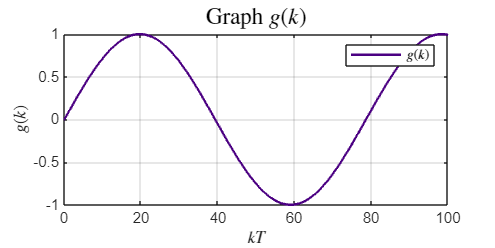


G1 = -1;
G2 = 2 * cos(0.016);
xi20 = sin(0.016);


open_system('schem_3');
set_param('schem_3/g', 'VariableName', 'g');

out = sim('schem_3');


y_data = out.g.Data;
t_time = out.g.Time;


% Определяем цвета для линий
a_color = '#4B0082'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);
stairs(t_time, y_data, '-', 'LineWidth', 1.5, 'Color', a_color);
hold on;
%plot(t_time, x_M_data(:,1), '--', 'LineWidth', 1.5, 'Color', d_color);
%plot(t_time, x_data(:,2), '-', 'LineWidth', 1.5, 'Color', e_color);
%plot(t_time, x_M_data(:,2), '--', 'LineWidth', 1.5, 'Color', c_color);

grid on;
%title('Graph $y(t)$, $z_{1,2} = \pm 0.2i $', 'Interpreter', 'latex', 'FontSize', 14);
title('Graph $g(k)$', 'Interpreter', 'latex', 'FontSize', 14);

%title(sprintf('Graph $y(t)$, $z_1 = %.1f$, $z_2 = %.1f$', z1, z2), 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$g(k)$','Interpreter', 'latex' );
xlabel('$kT$', 'Interpreter', 'latex');
legend('$g(k)$','Interpreter', 'latex')
%xlim([0 5])
hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_1\Discrete_report_1\pic\' ...
    '3_1_g.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);